type("pendulumCT0.m")


function dxdt = pendulumCT0(x, u)
%% Continuous-time nonlinear dynamic model of a pendulum on a cart
%
% 4 states (x): 
%   cart position (z)
%   cart velocity (z_dot): when positive, cart moves to right
%   angle (theta): when 0, pendulum is at upright position
%   angular velocity (theta_dot): anti-clockwise positive
% 
% 1 inputs: (u)
%   force (F): when positive, force pushes cart to right 
%
% Copyright 2018 The MathWorks, Inc.

%#codegen

%% parameters
M = 1;      % cart mass
m = 1;      % pendulum mass
g = 9.81;   % gravity of earth
l = 0.5;    % pendulum length
Kd = 10;    % cart damping

%% Obtain x, u and y

% x (state variables)
z_dot = x(2);
theta = x(3);
theta_dot = x(4);

% u (input variable)
F = u;

%% Compute dxdt
dxdt = [

    z_dot;...

    (   F - Kd*z_dot ...
        - m*l*theta_dot^2*sin(theta) ...
        + m*g*sin(theta)*cos(theta)  ...
    )/(M + m*sin(theta)^2);...
    
    theta_dot;...

    (  g*sin(theta) + ...
       (F - Kd*z_dot - m*l*theta_dot^2*sin(the


nx = 4;
ny = 2;
nu = 1;
nlobj = nlmpc(nx, ny, nu);

Zero weights are applied to one or more OVs because there are fewer MVs than OVs.



Ts = 0.1;
nlobj.Ts = Ts;

nlobj.PredictionHorizon = 10;

nlobj.ControlHorizon = 5;

type("pendulumDT0.m")


function xk1 = pendulumDT0(xk, uk, Ts)
%% Discrete-time nonlinear dynamic model of a pendulum on a cart at time k
%
% 4 states (xk): 
%   cart position (z)
%   cart velocity (z_dot): when positive, cart moves to right
%   angle (theta): when 0, pendulum is at upright position
%   angular velocity (theta_dot): anticlockwise positive
% 
% 1 inputs: (uk)
%   force (F): when positive, force pushes cart to right 
%
% xk1 is the states at time k+1.
%
% Copyright 2018 The MathWorks, Inc.

%#codegen

% Repeat application of Euler method sampled at Ts/Nd.
Nd = 10;
delta = Ts/Nd;
xk1 = xk;
for ct=1:Nd
    xk1 = xk1 + delta*pendulumCT0(xk1,uk);
end
% Note that we choose the Euler method (first order Runge-Kutta method)
% because it is more efficient for plant with non-stiff ODEs.  You can
% choose other ODE solvers such as ode23, ode45 for better accuracy or
% ode15s and ode23s for stiff ODEs.  Those solvers are available from
% MATLAB.



nlobj.Model.StateFcn = "pendulumDT0";

nlobj.Model.IsContinuousTime = false;

nlobj.Model.NumberOfParameters = 1;

nlobj.Model.OutputFcn = 'pendulumOutputFcn';

nlobj.Jacobian.OutputFcn = @(x,u,Ts) [1 0 0 0; 0 0 1 0];

nlobj.Weights.OutputVariables = [3 3];
nlobj.Weights.ManipulatedVariablesRate = 0.1;

nlobj.OV(1).Min = -10;
nlobj.OV(1).Max = 10;

nlobj.MV.Min = -100;
nlobj.MV.Max = 100;

x0 = [0.1;0.2;-pi/2;0.3];
u0 = 0.4;
validateFcns(nlobj,x0,u0,[],{Ts});

Model.StateFcn is OK.
Model.OutputFcn is OK.
Jacobian.OutputFcn is OK.
Analysis of user-provided model, cost, and constraint functions complete.


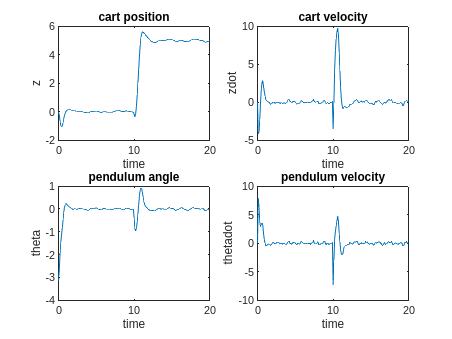


EKF = extendedKalmanFilter(@pendulumStateFcn, @pendulumMeasurementFcn);

x = [0;0;-pi;0];
y = [x(1);x(3)];
EKF.State = x;

mv = 0;

yref1 = [0 0];

yref2 = [5 0];

nloptions = nlmpcmoveopt;
nloptions.Parameters = {Ts};

Duration = 20;
hbar = waitbar(0,'Simulation Progress');
xHistory = x;
for ct = 1:(20/Ts)
    if ct*Ts<10
        yref = yref1;
    else
        yref = yref2;
    end
    xk = correct(EKF, y);
    [mv,nloptions,info] = nlmpcmove(nlobj,xk,mv,yref,[],nloptions);
    predict(EKF, [mv; Ts]);
    x = pendulumDT0(x,mv,Ts);
    y = x([1 3]) + randn(2,1)*0.01; 
    xHistory = [xHistory x]; %#ok<*AGROW>
    waitbar(ct*Ts/20,hbar);
end
close(hbar)

figure
subplot(2,2,1)
plot(0:Ts:Duration,xHistory(1,:))
xlabel('time')
ylabel('z')
title('cart position')
subplot(2,2,2)
plot(0:Ts:Duration,xHistory(2,:))
xlabel('time')
ylabel('zdot')
title('cart velocity')
subplot(2,2,3)
plot(0:Ts:Duration,xHistory(3,:))
xlabel('time')
ylabel('theta')
title('pendulum angle')
subplot(2,2,4)
plot(0:Ts:Duration,xHistory(4,:))
xlabel('time')
ylabel('thetadot')
title('pendulum velocity')